% initSim
s = tf('s')

s =
 
  s
 
Continuous-time transfer function.
Model Properties


% L_f = l_f*Lbase1v
% R_f = r_f*Zbase1v
% C_f = 0.0757204*Cbase1v
% c_f = 0.0757

% plant
    
G_plant = 1/(s*l_f/omega_nom+r_f)

G_plant =
 
       314.2
  ----------------
  0.1056 s + 1.658
 
Continuous-time transfer function.
Model Properties


T_delay = 0.1e-3

T_delay = 1.0000e-04

% G_sensor = 1/(1+s*T_delay)
G_i = G_plant;%*G_sensor

% f_sw = 10000
f_c = 1/5*f_sw

f_c = 590



Kp_cc =  1.33      

Kp_cc = 1.3300

Ti_cc =  0.005

Ti_cc = 0.0050

% G_cc = Kp_cc * (1+s*Ki_cc)/(s*Ki_cc)  
G_cc = Kp_cc*(1+1/Ti_cc/s)%Kp_cc*(1 + s*Ti_cc)/(s*Ti_cc);

G_cc =
 
  1.33 s + 266
  ------------
       s
 
Continuous-time transfer function.
Model Properties


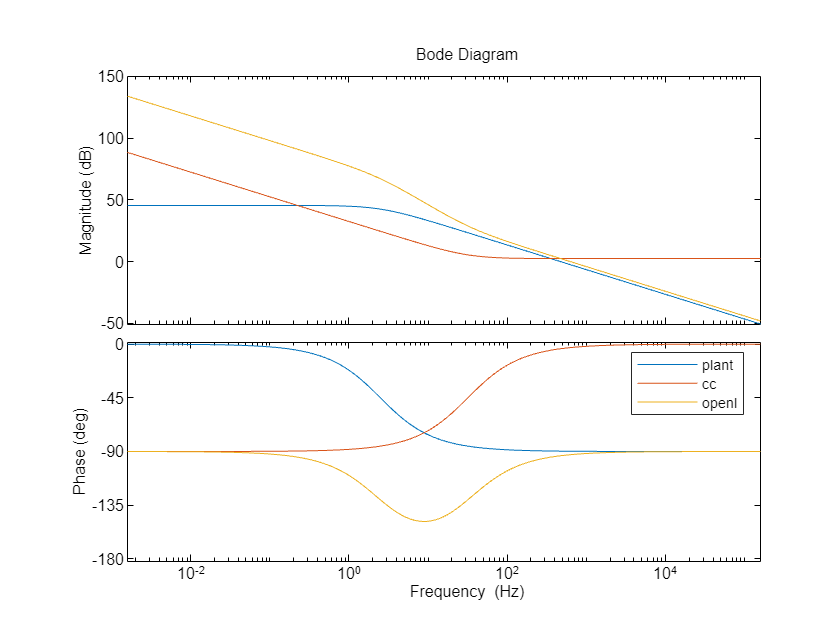

% Kp_cc*(1+1/Ti_cc/s)

% Ki_cc = Kp_cc/Ti_cc

% Kp_cc+Ki_cc/s

G_openl = G_cc*G_i;


options = bodeoptions;
options.FreqUnits = 'Hz'; % or 'rad/second', 'rpm', etc.
options.PhaseWrapping='on';


bode(G_i,G_cc,G_openl,{10e-3,10e5}, options)
legend('plant', 'cc','openl')

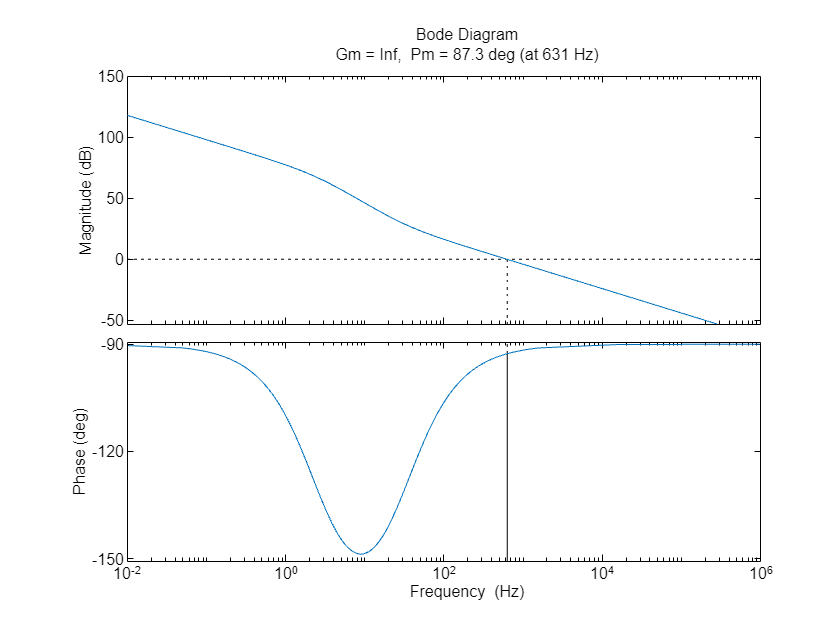

% bode(G_cc/(1+G_cc),{10e-3,10e5})

options.XLim = [10e-3,10e5];
% 
margin(G_openl,options)

% margin(G_cl)
G_cl = G_openl/(1+G_openl)

G_cl =
 
         44.11 s^3 + 9516 s^2 + 1.386e05 s
  -----------------------------------------------
  0.01115 s^4 + 44.46 s^3 + 9518 s^2 + 1.386e05 s
 
Continuous-time transfer function.
Model Properties


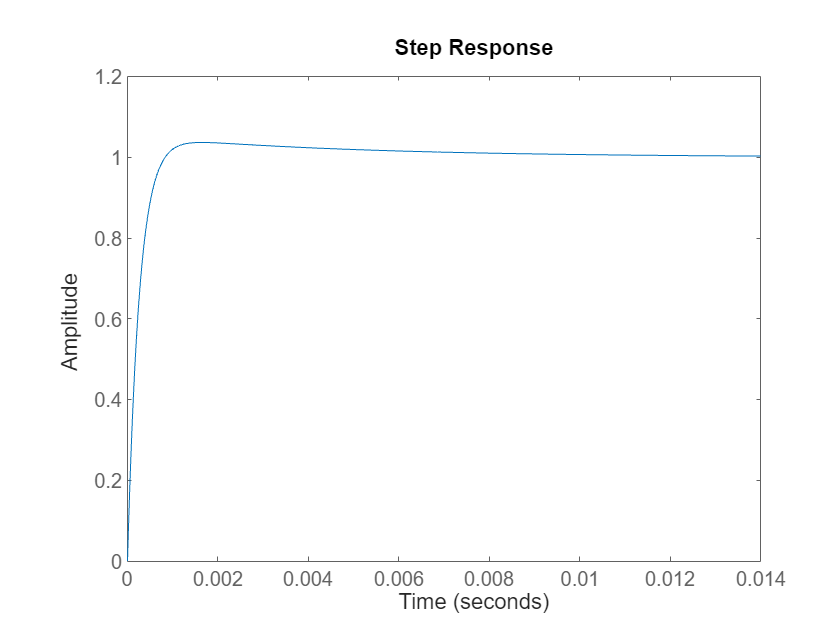

step(G_cl)

% pzmap(G_cl)

T_ers = 1/(2*pi*f_c)

T_ers = 2.6975e-04

Gapprox = 1/(1+s*T_ers)

Gapprox =
 
         1
  ---------------
  0.0002698 s + 1
 
Continuous-time transfer function.
Model Properties


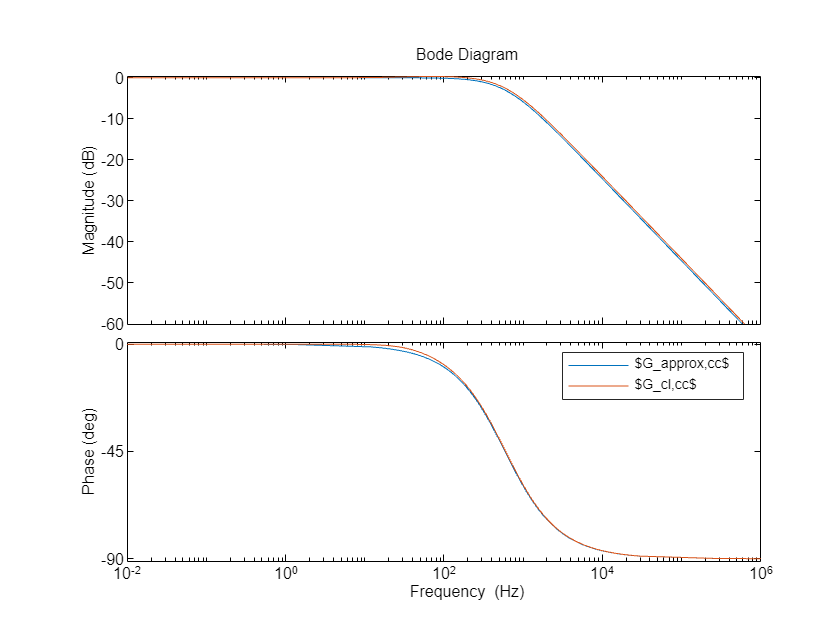

bode(Gapprox,G_cl,options)
legend('$G_{approx,cc}$','$G_{cl,cc}$')


Gu=1/(s*c_f/omega_nom);%(3/2*UNd-s*L*P0/UNd)/(s*UDC*C);
Gstr=Gapprox*Gu;




kpu=0.32;
Tnu=0.007;
Gcu=kpu*(1+1/Tnu/s)

Gcu =
 
  0.32 s + 45.71
  --------------
        s
 
Continuous-time transfer function.
Model Properties



Golu=Gcu*Gstr;
get(Golu,'Denominator')

ans = 1×1 cell array
    {[2.0420e-05 0.0757 0 0]}


pole(Golu)

ans = 1.0e+03 *

         0
         0
   -3.7071


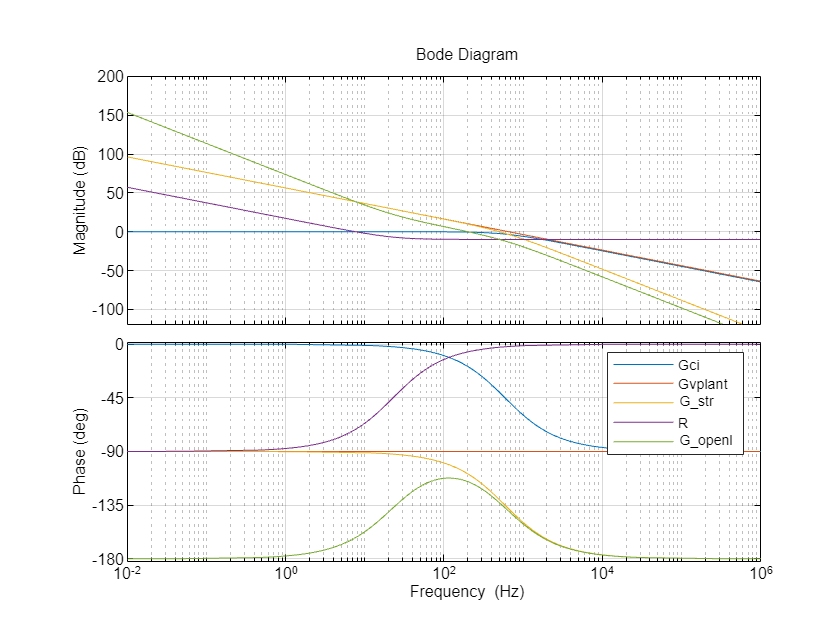

Gclu=Golu/(1+Golu); 

figure(3);
bode(Gapprox, Gu, Gstr,Gcu,Golu,options);
legend('Gci', 'Gvplant', 'G_{str}','R','G_{openl}');
grid on;

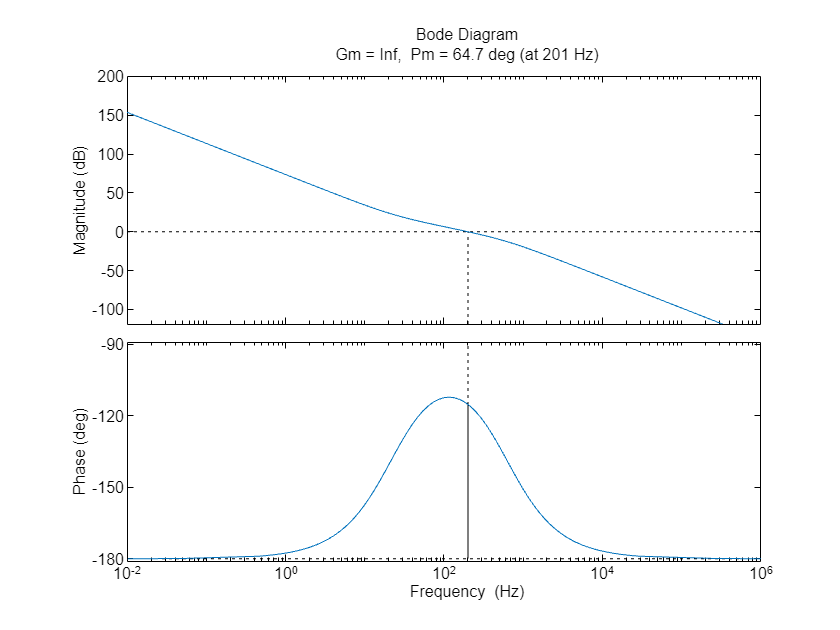

figure(4);
margin(Golu,options)

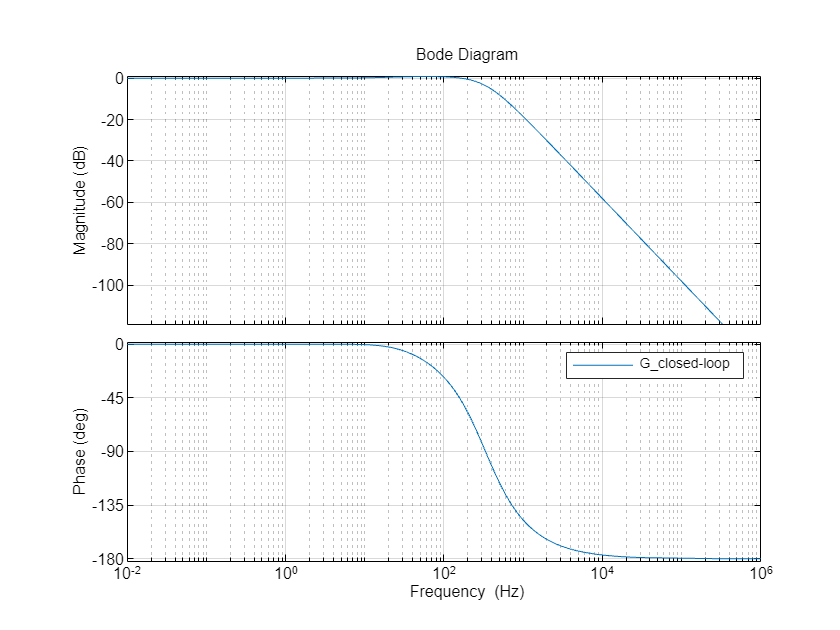

figure(5);
bode(Gclu,options);
legend('G_{closed-loop}');
grid on;


G_dcplant = 1/(s*(2*c_dc/omega_nom))

G_dcplant =
 
      1
  ----------
  0.001273 s
 
Continuous-time transfer function.
Model Properties


kp_dc = 0.8%5;

kp_dc = 0.8000

Ti_dc = 0.005%0.004;

Ti_dc = 0.0050

G_dcpi = kp_dc*(1+s*Ti_dc)/(s*Ti_dc)

G_dcpi =
 
  0.004 s + 0.8
  -------------
     0.005 s
 
Continuous-time transfer function.
Model Properties



G_dc_openloop = G_dcpi*G_dcplant

G_dc_openloop =
 
  0.004 s + 0.8
  -------------
  6.365e-06 s^2
 
Continuous-time transfer function.
Model Properties


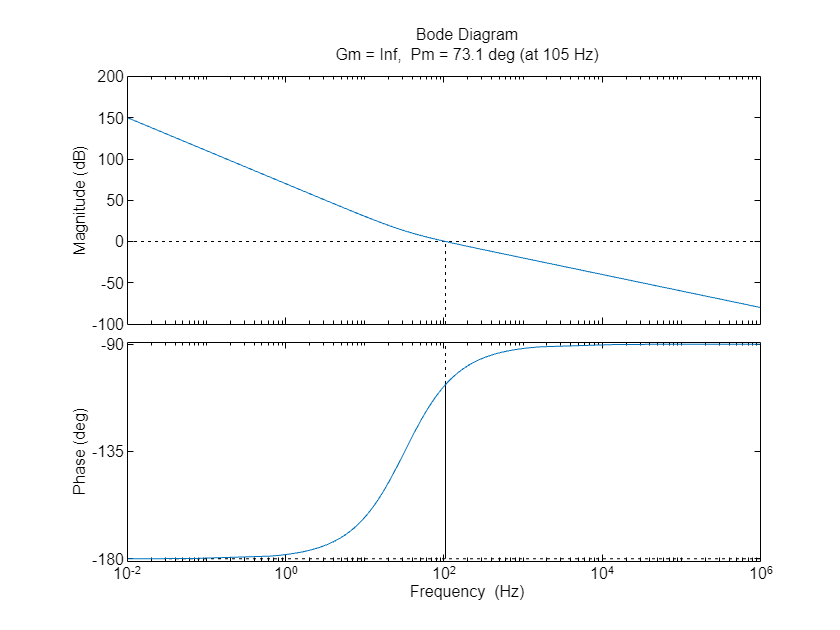

margin(G_dc_openloop,options)


G_dc_closed = G_dc_openloop/(1+G_dc_openloop)

G_dc_closed =
 
          2.546e-08 s^3 + 5.092e-06 s^2
  ---------------------------------------------
  4.051e-11 s^4 + 2.546e-08 s^3 + 5.092e-06 s^2
 
Continuous-time transfer function.
Model Properties


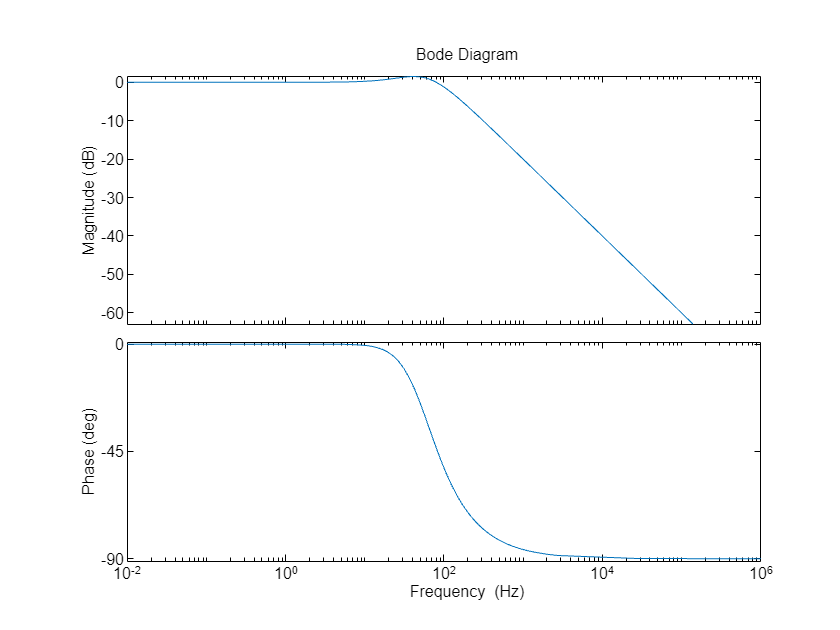

bode(G_dc_closed,options)

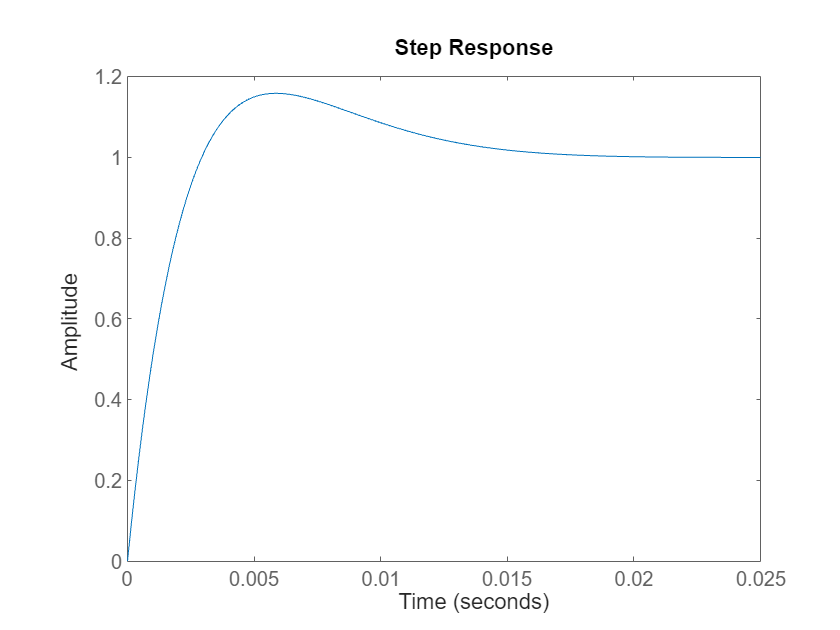

step(G_dc_closed)

## VSM

% 
 k_d_vsm=100.4281;%70%

% % 
H_vsm = 2.3388;%
T_vsm = tf([omega_nom/(2*H_vsm*x_sys)*cos(0)],[1 k_d_vsm/(2*H_vsm) omega_nom/(2*H_vsm*x_sys/1)*cos(0)])

G_vsm = omega_nom/(s*(2*H_vsm*s+k_d_vsm))
G_sync = 1/x_sys
G_ol_vsm = G_vsm*G_sync
G_cl_vsm = G_ol_vsm/(1+G_ol_vsm)
zeta_vsm = k_d_vsm/(4*H_vsm*sqrt(omega_nom/(2*H_vsm*x_sys)))
nf_vsm = sqrt(omega_nom/(2*H_vsm*x_sys))
step(G_ol_vsm/(1+G_ol_vsm))
exp(-pi*zeta_vsm/sqrt(1-zeta_vsm^2))
(pi-atan(sqrt(1-zeta_vsm^2))/zeta_vsm)/(0.8*sqrt(1-zeta_vsm^2))
pzmap(G_ol_vsm/(1+G_ol_vsm))

## Q-Droop

k_p_q_vsm = -0.05
ki_q = 2*pi*50


% %closed loop 
% T_q_vsm = tf([ki_q*k_p_q_vsm/x_sys],[1 ki_q+k_p_q_vsm*ki_q/x_sys])
% 
% %open loop Q_grid -> delta V_d_ref
% G_qdroop = tf([ki_q*k_p_q_vsm],[1 ki_q])
% 
% % step(T_q_vsm)
% % step(T_e_vsm)
% 
% % pzmap(T_q_vsm)